  files = ["./pca_fixed/fixedata.ply", "./busako_printed_scan/busako_printed_scan025_2ROT.stl", ...
    "./stl/Busako_printed_scan025_fix.stl", "./pca_fixed/Nov15_pcafix.ply", ...
    "./stl/busako_naname_reScale.stl", "./stl/NonHoof_Obj27_13Pro.stl", "./stl/xvector1.stl", ...
    "./stl/busakoLH_obj66.stl", "./stl/busakoLH_obj66_x+60.stl", "./stl/busakoLH_obj66rescale.stl"];

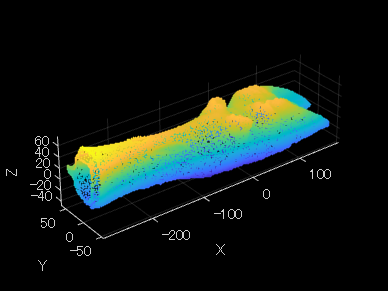

% filename = uigetfile({'*.stl';'*.ply'});
% filename = files(10);
filename = uigetfile(".stl");
if contains(filename, 'stl')
    mesh = stlread(filename);
    scale = 1000;
    pt = (mesh.Points).*scale;
%     pt = mesh.Points;
    importPoint = pointCloud(pt);
elseif contains(filename, 'ply')
    importPoint = pcread(filename);
else
    disp('Not Found');

end
pcshowWithAxes(importPoint, "import");

cutWidthT = 0.5;
axesString = ["x","y","z"];
axes = axesString(1);

一度周囲長と断面積を計算

sPoint = fixLegsDirection(importPoint, axes, cutWidthT);
if sPoint.Location ~= importPoint.Location
    pcshowWithAxes(sPoint);
else
    disp("Nothing Change!");
end

Nothing Change!


もし蹄が負の方向を向いていたら、正の方向へ反転させる

新しいデータ上で解析

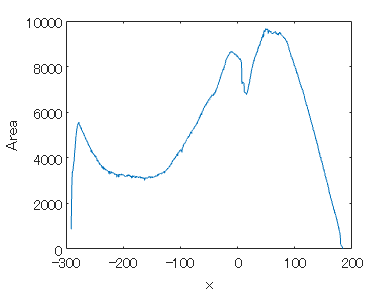

CircumData= CalculateCircum(sPoint, axes, cutWidthT);
x = CircumData(:,1);
area = CircumData(:,3);
[areaMax, I] = max(area);
figure('Name','firstPlot')
plot(x,area);
xlabel('x');ylabel('Area');

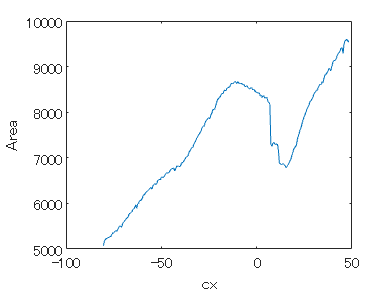

cutData = CircumData(CircumData(:,1) > x(I)-130 & x(I) > CircumData(:,1), :);
cx  = cutData(:,1);
cArea = cutData(:,3);
figure('Name', 'Cut at AreaMax');
plot(cx, cArea);
xlabel('cx');ylabel('Area');

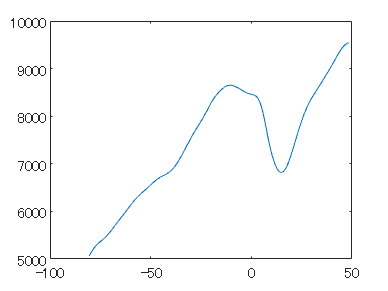


n = 3;
Wn = 0.1;
[y1, v1, v2] = filterAnddiff(cArea, n, Wn);

figure('Name','Filtering');
plot(cx,y1);

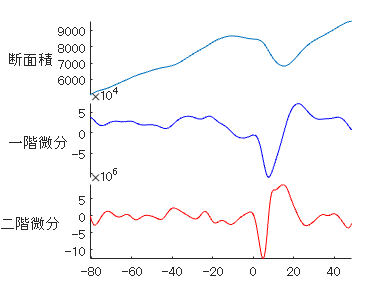

figure;
newLabels = ["断面積", "一階微分", "二階微分"];
s = stackedplot(cx, [y1, v1, v2], 'DisplayLabels',newLabels, 'Color','r');
s.LineProperties(1).Color = '#0072BD';
s.LineProperties(2).Color = 'b';
s.LineProperties(3).Color = 'r';

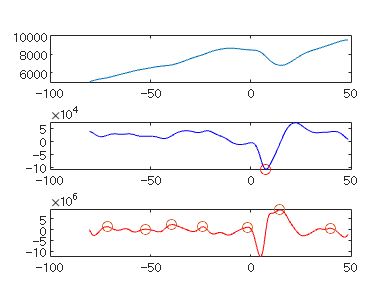

TF = islocalmin(v1, 'MaxNumExtrema',1 );

[pkv2, locv2] = findpeaks(v2, cx, 'MinPeakDistance',10, 'Annotate','extents');

figure('Name', 'subplot');
subplot(3, 1,1);
plot(cx, y1);
subplot(3,1,2);
% plot(cx,v1,'b',locv1,pkv1, 'o');
plot(cx,v1,'b',cx(TF),v1(TF), 'ro');
subplot(3, 1, 3);
plot(cx, v2,'r',locv2, pkv2, 'o');

% 一階微分の局所最小値以下の解析
recutData = cutData(cutData(:,1) < cx(TF)-10, :);
rx = recutData(:,1);
rArea = recutData(:,3);

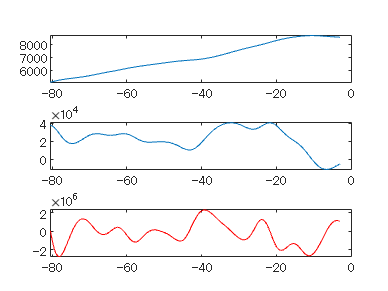

n = 3;
Wn = 0.1;
[yr, v1_r, v2_r] = filterAnddiff(rArea, n, Wn);
subplot(3,1,1);
plot(rx, yr);
subplot(3,1,2);
plot(rx,v1_r);
subplot(3,1,3)
plot(rx, v2_r, 'r');

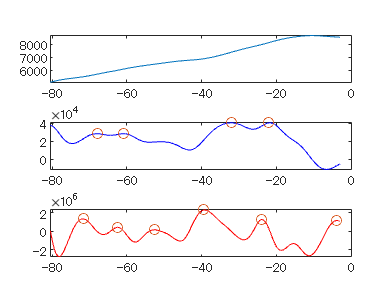



[pkv1_r, locv1_r, width1, proms1] = findpeaks(v1_r, rx, 'MinPeakHeight',20000);
[pkv2_r, locv2_r, wudth2, proms2] = findpeaks(v2_r, rx, 'MinPeakHeight',25000);

figure('Name', 'Second Range Search');
subplot(3,1,1);
plot(rx, yr);
subplot(3,1,2);
plot(rx,v1_r,'b', locv1_r, pkv1_r,'o');
subplot(3,1,3)

plot(rx, v2_r, 'r', locv2_r, pkv2_r, 'o');

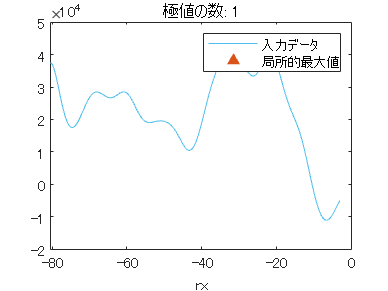

% 局所的最大値の検出
maxIndices = islocalmax(v1_r,"MaxNumExtrema",1,"SamplePoints",rx);

% 結果の表示
figure
plot(rx,v1_r,"Color",[77 190 238]/255,"DisplayName","入力データ")
hold on

% 局所的最大値のプロット
plot(rx(maxIndices),v1_r(maxIndices),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","局所的最大値")
title("極値の数: " + nnz(maxIndices))
hold off
legend
xlabel("rx")

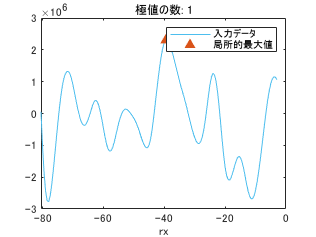

% 局所的最大値の検出
maxIndices2 = islocalmax(v2_r,"MaxNumExtrema",1,"SamplePoints",rx);

% 結果の表示
figure
plot(rx,v2_r,"Color",[77 190 238]/255,"DisplayName","入力データ")
hold on

% 局所的最大値のプロット
plot(rx(maxIndices2),v2_r(maxIndices2),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","局所的最大値")
title("極値の数: " + nnz(maxIndices2))
hold off
legend
xlabel("rx")

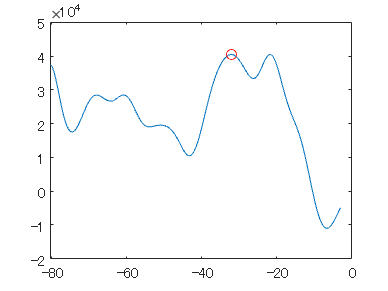

mTF = islocalmax(v1_r, 'MinProminence',20000, 'MaxNumExtrema',2);
plot(rx, v1_r, rx(mTF), v1_r(mTF), 'ro');

localMaxSet = [rx(mTF) v1_r(mTF)];
disp(localMaxSet);

   1.0e+04 *

  -0.003200845956802   4.052038366386902



[maxPoint, I] = max(localMaxSet(:,2));
rx_extream = localMaxSet(I);
disp(localMaxSet(I,2));

     4.052038366386902e+04



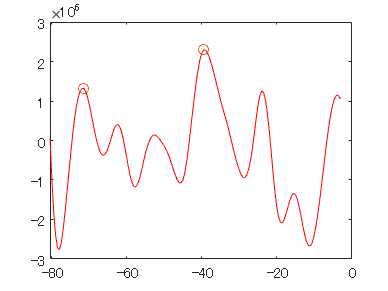


mTF2 = islocalmax(v2_r, 'MinProminence',10000, 'MaxNumExtrema',2);
plot(rx, v2_r, 'r',rx(mTF2), v2_r(mTF2), 'o');

localMaxSet2 = [rx(mTF2) v2_r(mTF2)]; 
[max2, I2]  = max(localMaxSet2(:,2));
rx_ex2 = localMaxSet2(I2);


samplingWidth = 5;
% samplemin = rx(mTF)-samplingWidth;
% samplemax = rx(mTF);
samplemin = rx_extream-samplingWidth;
samplemax = rx_extream;

% samplemin2 = rx_ex2-(samplingWidth/2);
% samplemax2 = rx_ex2+(samplingWidth/2);
cent =  (rx_ex2 + rx_extream) /2

cent =  -35.758459568023682


samplemin2 = cent-(samplingWidth/2);
samplemax2 = cent+(samplingWidth/2);

samplemax3 = rx_ex2 + samplingWidth;
samplemin3 = rx_ex2

samplemin3 =  -39.508459568023682



sampleData = recutData(recutData(:,1) > samplemin & samplemax > recutData(:,1),:);
sampleDataf2 =  recutData(recutData(:,1) > samplemin2 & samplemax2 > recutData(:,1),:);
% s3 =  recutData(recutData(:,1) > rx_ex2 & rx_extream > recutData(:,1),:);
sampleDataf3 =  recutData(recutData(:,1) > samplemin3 & samplemax3 > recutData(:,1),:);
sampleDataf4 = recutData(recutData(:,1) > rx_ex2 & rx_extream > recutData(:,1),:);
Circum = mean(sampleData(:,2));
Cir_f2 = mean(sampleDataf2(:,2));
C3 = mean(sampleDataf3(:,2));
C4 = mean(sampleDataf4(:,2));

fprintf('%f < dt < %fの時, 平均周囲長は %f \n',samplemin, samplemax, Circum);

-37.008460 < dt < -32.008460の時, 平均周囲長は 303.805119 


fprintf('%f < dt < %fの時, 平均周囲長は %f \n',samplemin2, samplemax2, Cir_f2);

-38.258460 < dt < -33.258460の時, 平均周囲長は 301.559296 


fprintf('%f < dt < %fの時, 平均周囲長は %f \n',samplemin3, samplemax3, C3);

-39.508460 < dt < -34.508460の時, 平均周囲長は 299.390259 


fprintf('%f < dt < %fの時, 平均周囲長は %f \n',rx_ex2, rx_extream, C4);

-39.508460 < dt < -32.008460の時, 平均周囲長は 301.655292 


% pcshowWithAxes(sPoint, 'marking');
% hold on;
sP = sPoint.Location;
idx = 1

idx =      1


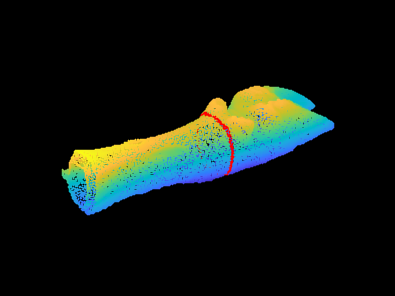

samplePoint = sP(sP(:,idx) > samplemin & sP(:,idx) < samplemax, :);
samplePointf2 = sP(sP(:,idx) > samplemin2 & sP(:,idx) < samplemax2, :);
samp3 = sP(sP(:,idx) > samplemin3 & sP(:,idx) < samplemax3, :);
% pcshow(samplePoint,'r');
% pcshow(samplePointf2, 'm');
pcshowWithAxes(sPoint, 'marking1');
hold on;
pcshow(samplePoint, 'r');
hold off;

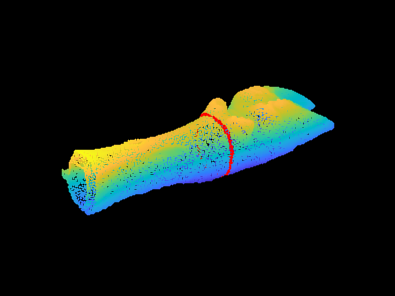

pcshowWithAxes(sPoint, 'marking2');
hold on;
pcshow(samplePointf2, 'r');
hold off;

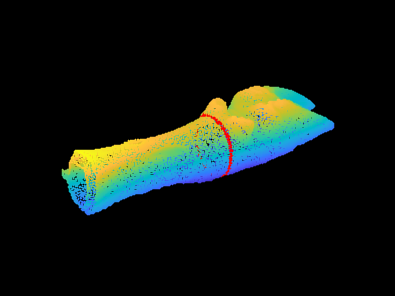

pcshowWithAxes(sPoint, 'marking3');
hold on;
pcshow(samp3, 'r');
hold off;

[FData, FPoints] = sliceData(sPoint, 'x', cutWidthT);

% 第一区間探索
pos = FData(:,1);
area = FData(:,3);
[~, I] = max(area);
%　蹄断面積最大位置から130のところまで
cutData = FData(FData(:,1) > pos(I)-130 & pos(I) > FData(:,1),:);
cPos = cutData(:,1);
cArea = cutData(:,3);
%　フィルター処理と微分
[y1, v1, v2] = filterAnddiff(cArea, n, Wn);
TF = islocalmin(v1, 'MaxNumExtrema',1);
%　第二区間探索
RecutData = cutData(cutData(:,1) < cPos(TF)-10, :);
rPos = RecutData(:,1);
rArea = RecutData(:,3);

[yr, v1_r, v2_r] = filterAnddiff(rArea);
mTF = islocalmax(v1_r, 'MinProminence',20000, 'MaxNumExtrema',2);
localMaxSet = [rPos(mTF) v1_r(mTF)];
[~, I] = max(localMaxSet(:,2));
rx_extream2 = localMaxSet(I);
disp(localMaxSet(I,2));

     5.050329336279340e+04




samplemin2 = rx_extream2-1-samplingWidth;
samplemax2 = rx_extream2-1;

index = FData(:,1) > samplemin2 & samplemax2 > FData(:,1);
sampleData = FData(index, :);
samplePt = FPoints(index, :);
% 平均周囲長
Circumslice  = mean(sampleData(:,2));
sp = sPoint.Location;
samplePoint = sp(sp(:,1) > samplemin2 & sp(:, 1) < samplemax2, :);

fprintf('%f < dt < %fの時, 平均周囲長は %f \n',samplemin2, samplemax2, Circumslice);

-27.008460 < dt < -22.008460の時, 平均周囲長は 322.521947 


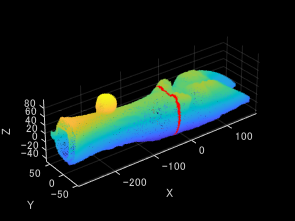

pcshowWithAxes(sPoint, 'Marking');
hold on; grid on;
pcshow(samplePoint, 'r', 'AxesVisibility','on');
hold off;